% 设置中文显示
set(groot, 'DefaultTextFontName', 'Kaiti');
set(groot, 'DefaultAxesFontName', 'Kaiti');

%% 1. 生成模拟天气数据
rng(42);  % 设置随机种子

% 定义天气状态
weather_states = {'晴天', '阴天', '雨天'};
n_states = length(weather_states);

% 定义真实的转移概率矩阵
true_transition_matrix = [
    0.7, 0.2, 0.1;  % 晴天 -> [晴天, 阴天, 雨天]
    0.3, 0.4, 0.3;  % 阴天 -> [晴天, 阴天, 雨天]
    0.2, 0.3, 0.5   % 雨天 -> [晴天, 阴天, 雨天]
];

%% 生成天气序列
function sequence = generate_weather_sequence(n_days, initial_state, transition_matrix)
    % 生成n天的天气序列
    sequence = zeros(1, n_days);
    sequence(1) = initial_state;
    current_state = initial_state;
    
    for i = 2:n_days
        % 根据当前状态和转移概率选择下一个状态
        probabilities = transition_matrix(current_state, :);
        next_state = randsample(length(probabilities), 1, true, probabilities);
        sequence(i) = next_state;
        current_state = next_state;
    end
end

% 生成30天的历史数据
historical_days = 30;
weather_sequence = generate_weather_sequence(historical_days, 1, true_transition_matrix);
weather_names = cell(1, historical_days);
for i = 1:historical_days
    weather_names{i} = weather_states{weather_sequence(i)};
end

% 创建数据表格
dates = datetime('2025-01-01') + caldays(0:historical_days-1);
df = table(dates', weather_names', weather_sequence', ...
    'VariableNames', {'日期', '天气状态', '状态编码'});

fprintf('历史天气数据（前10天）：\n');

历史天气数据（前10天）：


disp(df(1:10, :));

       日期        天气状态     状态编码
    ___________    ________    _______
    01-Jan-2025    {'晴天'}       1   
    02-Jan-2025    {'晴天'}       1   
    03-Jan-2025    {'雨天'}       3   
    04-Jan-2025    {'雨天'}       3   
    05-Jan-2025    {'雨天'}       3   
    06-Jan-2025    {'晴天'}       1   
    07-Jan-2025    {'晴天'}       1   
    08-Jan-2025    {'晴天'}       1   
    09-Jan-2025    {'阴天'}       2   
    10-Jan-2025    {'阴天'}       2   


fprintf('\n数据形状：%d行 %d列\n', size(df, 1), size(df, 2));


数据形状：30行 3列


%% 2. 估计转移概率矩阵
function [transition_matrix, transition_counts] = estimate_transition_matrix(sequence)
    % 从观察序列估计转移概率矩阵
    n_states = max(sequence);
    transition_counts = zeros(n_states, n_states);
    
    % 统计转移次数
    for i = 1:length(sequence)-1
        current_state = sequence(i);
        next_state = sequence(i+1);
        transition_counts(current_state, next_state) = transition_counts(current_state, next_state) + 1;
    end
    
    % 计算转移概率
    transition_matrix = zeros(n_states, n_states);
    for i = 1:n_states
        row_sum = sum(transition_counts(i, :));
        if row_sum > 0
            transition_matrix(i, :) = transition_counts(i, :) / row_sum;
        else
            % 如果某个状态没有出现，使用均匀分布
            transition_matrix(i, :) = ones(1, n_states) / n_states;
        end
    end
end

%% 估计转移概率矩阵
[estimated_matrix, counts_matrix] = estimate_transition_matrix(weather_sequence);

fprintf('\n转移次数矩阵：\n');


转移次数矩阵：


counts_df = array2table(counts_matrix, 'RowNames', weather_states, 'VariableNames', weather_states);
disp(counts_df);

            晴天    阴天    雨天
            ____    ____    ____
    晴天     15      2       2  
    阴天      2      1       1  
    雨天      2      1       3  



fprintf('\n估计的转移概率矩阵：\n');


估计的转移概率矩阵：


prob_df = array2table(round(estimated_matrix, 3), 'RowNames', weather_states, 'VariableNames', weather_states);
disp(prob_df);

            晴天     阴天     雨天 
            _____    _____    _____
    晴天    0.789    0.105    0.105
    阴天      0.5     0.25     0.25
    雨天    0.333    0.167      0.5


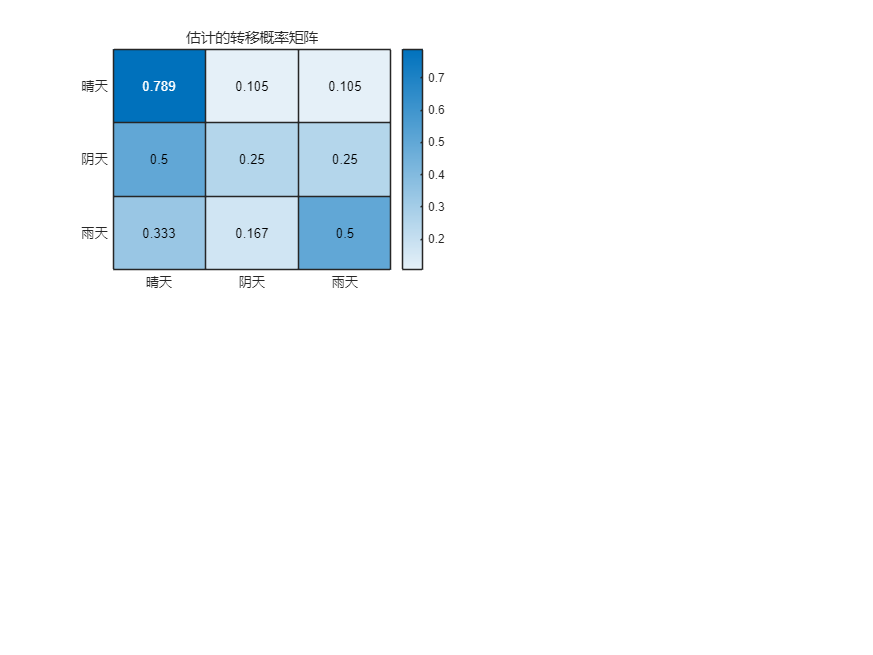

%% 3. 可视化转移概率矩阵
figure('Position', [500, 500, 1600, 1200]);
tiledlayout(2, 2);
% 子图1：热力图
nexttile(1);
heatmap(weather_states, weather_states, round(estimated_matrix, 3), ...
    'Title', '估计的转移概率矩阵');

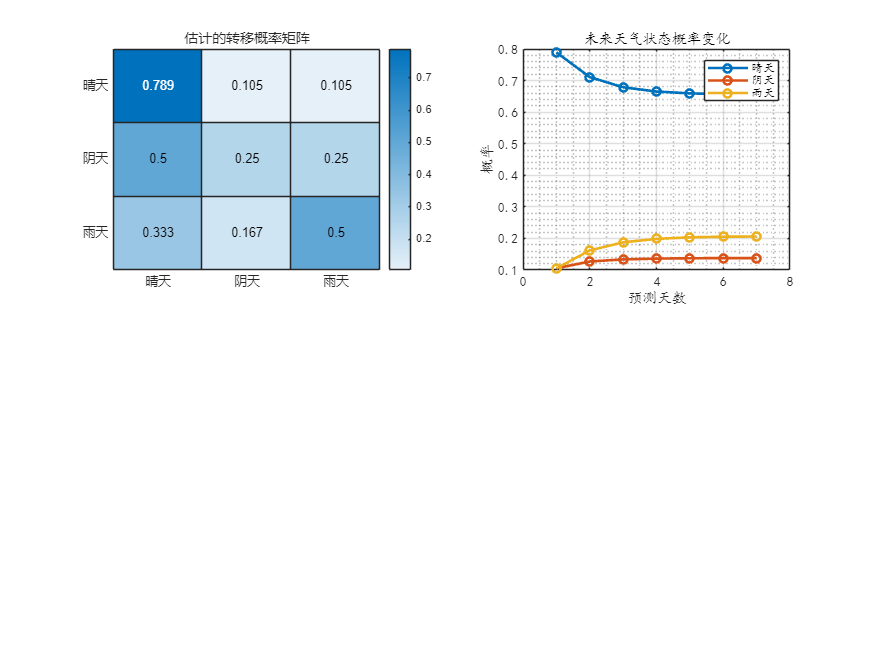

%% 4. 天气预测
function [predictions, state_probs] = predict_weather(current_state, transition_matrix, n_days)
    % 预测未来n天的天气
    n_states = size(transition_matrix, 1);
    predictions = zeros(1, n_days);
    state_probs = zeros(n_days, n_states);
    
    % 初始状态概率向量
    current_prob = zeros(1, n_states);
    current_prob(current_state) = 1.0;
    
    for day = 1:n_days
        % 计算下一天的状态概率
        current_prob = current_prob * transition_matrix;
        state_probs(day, :) = current_prob;
        
        % 选择最可能的状态作为预测
        [~, predicted_state] = max(current_prob);
        predictions(day) = predicted_state;
    end
end

%% 预测未来7天的天气
current_weather = weather_sequence(end);  % 使用最后一天的天气作为当前状态
forecast_days = 7;
[predictions, probabilities] = predict_weather(current_weather, estimated_matrix, forecast_days);

% 创建预测结果表格
forecast_dates = datetime(df.("日期")(end)) + days(1:forecast_days);
forecast_weather = cell(1, forecast_days);
for i = 1:forecast_days
    forecast_weather{i} = weather_states{predictions(i)};
end

forecast_df = table(forecast_dates', forecast_weather', ...
    probabilities(:, 1), probabilities(:, 2), probabilities(:, 3), ...
    'VariableNames', {'预测日期', '预测天气', '晴天概率', '阴天概率', '雨天概率'});
% 子图3：预测概率变化
nexttile(2);
days = 1:forecast_days;
plot(days, probabilities(:, 1), 'o-', 'LineWidth', 2, 'DisplayName', weather_states{1});
hold on;
plot(days, probabilities(:, 2), 'o-', 'LineWidth', 2, 'DisplayName', weather_states{2});
plot(days, probabilities(:, 3), 'o-', 'LineWidth', 2, 'DisplayName', weather_states{3});

xlabel('预测天数');
ylabel('概率');
title('未来天气状态概率变化');
legend();
grid on;
grid minor;

alpha(0.3);

%% 5. 计算稳态分布
function steady_state = compute_steady_state(transition_matrix)
    % 计算马尔可夫链的稳态分布
    n = size(transition_matrix, 1);
    A = transition_matrix' - eye(n);
    A = [A; ones(1, n)];
    b = zeros(n + 1, 1);
    b(end) = 1;
    
    % 使用最小二乘法求解
    steady_state = lsqnonneg(A, b);
    % 确保和为1
    steady_state = steady_state / sum(steady_state);
end

steady_state = compute_steady_state(estimated_matrix);

fprintf('\n稳态分布：\n');


稳态分布：


for i = 1:n_states
    fprintf('%s: %.3f\n', weather_states{i}, steady_state(i));
end

晴天: 0.655
阴天: 0.138
雨天: 0.207


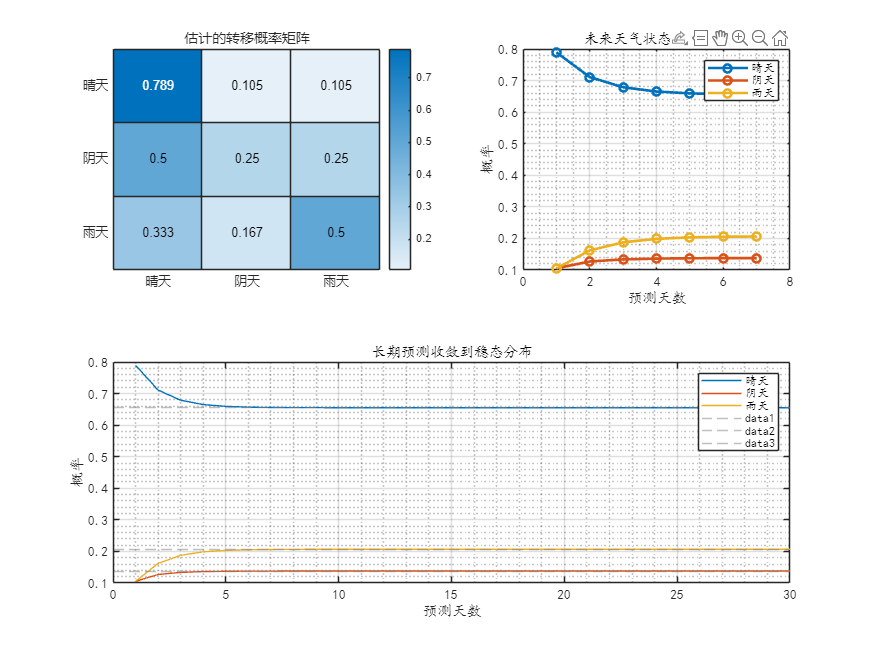


%% 子图4：长期预测vs稳态
nexttile([1, 2]);
long_term_days = 30;
[~, long_term_probs] = predict_weather(current_weather, estimated_matrix, long_term_days);

plot(1:long_term_days, long_term_probs(:, 1), 'DisplayName', weather_states{1});
hold on;
plot(1:long_term_days, long_term_probs(:, 2), 'DisplayName', weather_states{2});
plot(1:long_term_days, long_term_probs(:, 3), 'DisplayName', weather_states{3});

% 添加稳态水平线
yline(steady_state(1), '--', 'Color', [0.5, 0.5, 0.5], 'Alpha', 0.5);
yline(steady_state(2), '--', 'Color', [0.5, 0.5, 0.5], 'Alpha', 0.5);
yline(steady_state(3), '--', 'Color', [0.5, 0.5, 0.5], 'Alpha', 0.5);

xlabel('预测天数');
ylabel('概率');
title('长期预测收敛到稳态分布');
legend();
grid on;
grid minor;

alpha(0.3);


%% 6. 模型评估
function evaluate_markov_property(sequence, weather_states, estimated_matrix)
    % 检验序列的马尔可夫性
    n = length(sequence);
    n_states = length(weather_states);
    
    % 统计一阶转移
    first_order_counts = zeros(n_states, n_states);
    for i = 1:n-1
        first_order_counts(sequence(i), sequence(i+1)) = first_order_counts(sequence(i), sequence(i+1)) + 1;
    end
    
    % 统计二阶转移（考虑前两个状态）
    second_order_counts = containers.Map();
    for i = 1:n-2
        key = [sequence(i), sequence(i+1)];
        key_str = num2str(key);
        next_state = sequence(i+2);
        if ~isKey(second_order_counts, key_str)
            second_order_counts(key_str) = zeros(1, n_states);
        end
        counts = second_order_counts(key_str);
        counts(next_state) = counts(next_state) + 1;
        second_order_counts(key_str) = counts;
    end
    
    fprintf("\n马尔可夫性检验：\n");
    fprintf("如果满足马尔可夫性，P(X_t+1|X_t) 应该与 P(X_t+1|X_t,X_t-1) 相似\n");
    
    % 比较一阶和二阶转移概率
    keys_list = keys(second_order_counts);  % 这里是修正的地方
    for i = 1:length(keys_list)
        key_str = keys_list{i};
        key = str2num(key_str);
        prev_prev = key(1);
        prev = key(2);
        counts = second_order_counts(key_str);
        
        if sum(counts) > 5  % 只考虑有足够观察的情况
            second_order_prob = counts / sum(counts);
            first_order_prob = estimated_matrix(prev, :);
            diff = mean(abs(second_order_prob - first_order_prob));
            
            fprintf("\n从 (%s,%s) 出发:\n", weather_states{prev_prev}, weather_states{prev});
            fprintf("  二阶转移概率: %.3f %.3f %.3f\n", second_order_prob(1), second_order_prob(2), second_order_prob(3));
            fprintf("  一阶转移概率: %.3f %.3f %.3f\n", first_order_prob(1), first_order_prob(2), first_order_prob(3));
            fprintf("  平均差异: %.3f\n", diff);
        end
    end
end

evaluate_markov_property(weather_sequence, weather_states, estimated_matrix);


马尔可夫性检验：
如果满足马尔可夫性，P(X_t+1|X_t) 应该与 P(X_t+1|X_t,X_t-1) 相似

从 (晴天,晴天) 出发:
  二阶转移概率: 0.786 0.143 0.071
  一阶转移概率: 0.789 0.105 0.105
  平均差异: 0.025


%% 7. 生成更多数据进行验证
fprintf("\n\n使用更多数据验证模型：\n");



使用更多数据验证模型：


validation_sequence = generate_weather_sequence(1000, 1, true_transition_matrix);
[validation_matrix, ~] = estimate_transition_matrix(validation_sequence);

fprintf("大样本估计的转移概率矩阵：\n");

大样本估计的转移概率矩阵：


val_df = array2table(round(validation_matrix, 3), 'RowNames', weather_states, 'VariableNames', weather_states);
disp(val_df);

            晴天     阴天     雨天 
            _____    _____    _____
    晴天    0.701    0.175    0.123
    阴天    0.341    0.364    0.295
    雨天    0.174    0.308    0.518



fprintf("\n与真实矩阵的比较：\n");


与真实矩阵的比较：


mae = mean(abs(validation_matrix - true_transition_matrix), 'all');
fprintf("平均绝对误差：%.4f\n", mae);

平均绝对误差：0.0204



fprintf("\n分析完成！\n");


分析完成！
